# Do 1D model after mean removal

## setup DataSet object

[obj_arr, mset_arr] = make_objs();
epica_data = obj_arr{1};

Y = 20;
M = 10;
m = 5;

br_win = M*50;
close all;
[a_final,N,f,P_final] = findanf_epica(epica_data,Y,M,m,1,br_win);



Y = 34;
M = 10;
m = 1;

length(epica_data.Y)

ans = 1096

    10

    10

SUBTRACTING MOVING AVG
PLOTTING - 


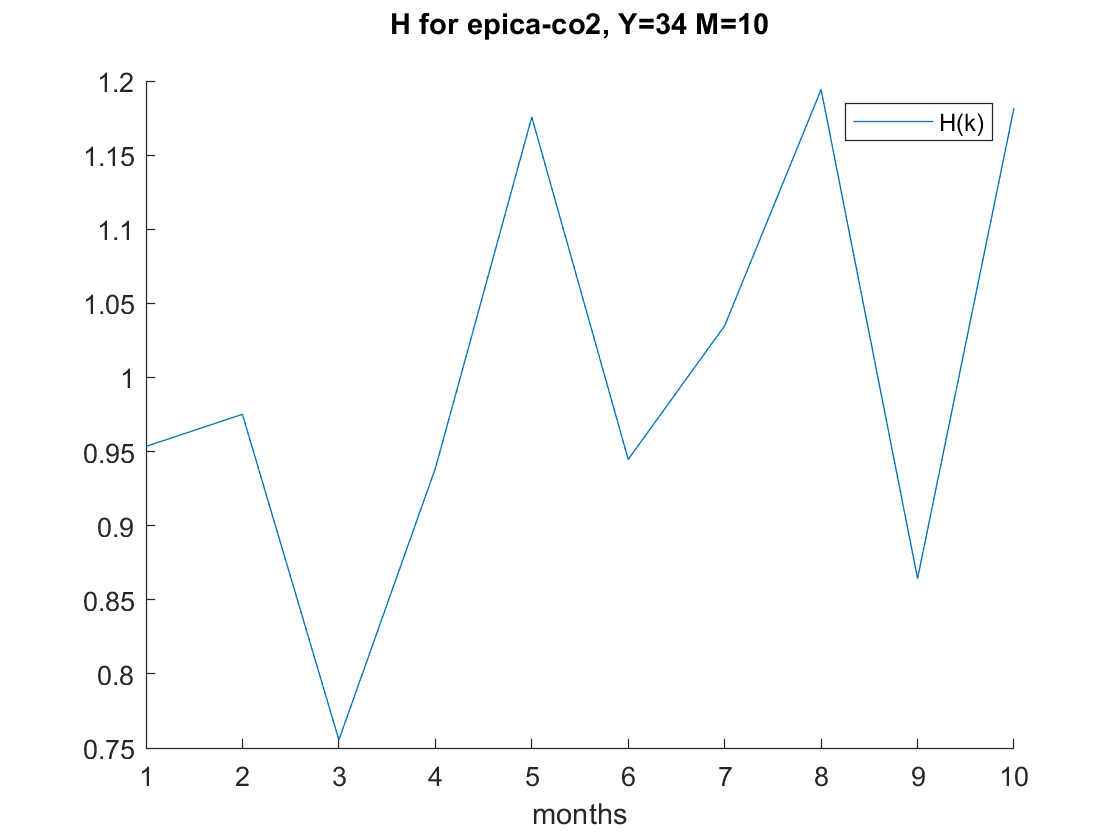

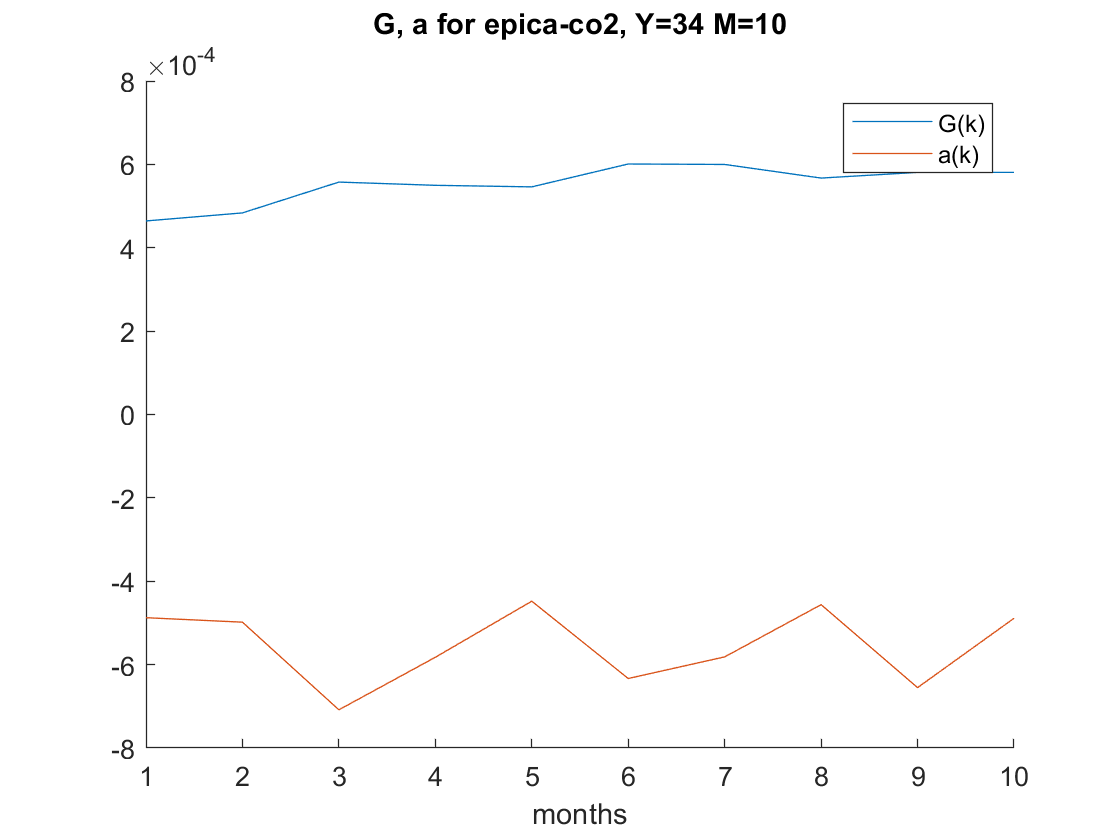

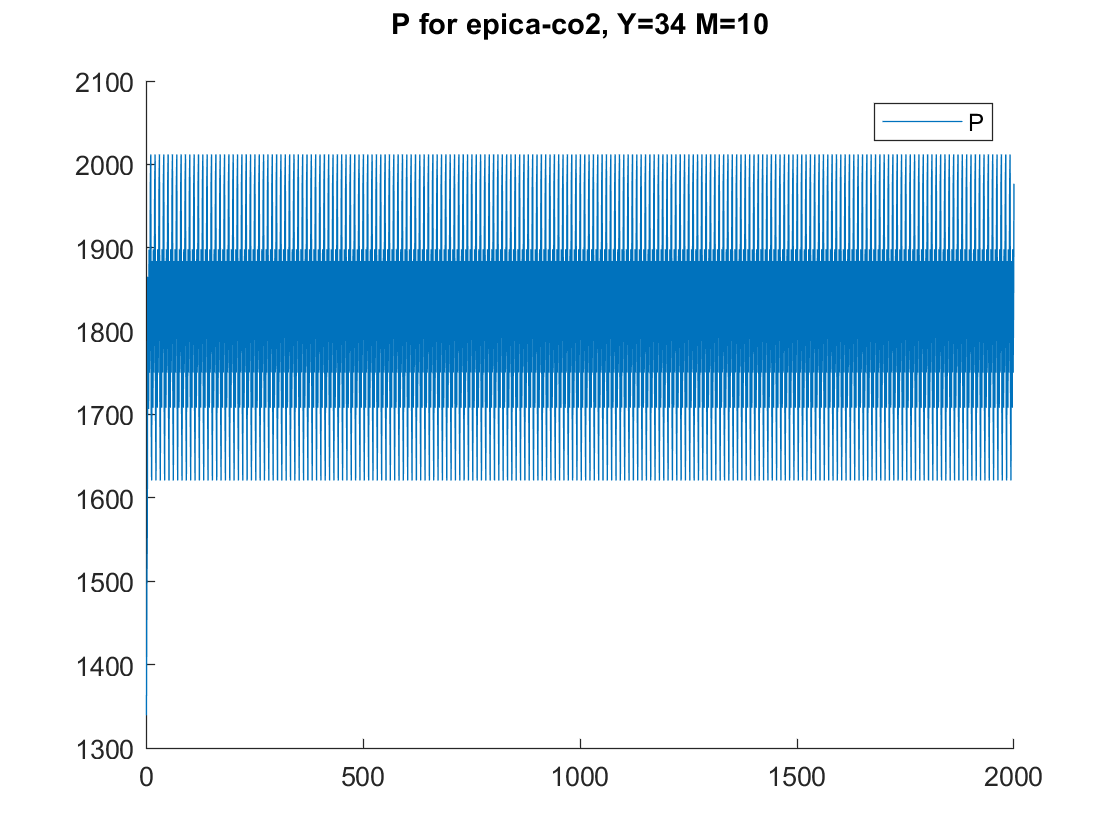


br_win = M;

[sim_x, sim_n] = epica_sim1D(epica_data,Y,M,m,1,br_win);

close all;

[matrix_x,matrix_y,M_length] = data2matrix(epica_data,Y,M,br_win);
matrix_x = reshape(matrix_x',[],1);
matrix_y = reshape(matrix_y',[],1);

plot(matrix_x,matrix_y);
plot(sim_x,sim_n);

close all;
figure(2);
hold on;

bins = 20;

histogram(matrix_y,bins);
histogram(sim_n,bins);

legend("interp data PDF","sim PDF");

data_noise = DataSet("vbl","noise-data",matrix_x,matrix_y);
sim_noise = DataSet("vbl","noise-sim",sim_x,sim_n);

[t_arr1,f_arr1] = mftwdfa(data_noise,{"makima",1000,2});
[t_arr2,f_arr2] = mftwdfa(sim_noise,{"makima",1000,2});
t_arr1


close all;
hold on;
plot(log10(t_arr1),log10(f_arr1));
plot(log10(t_arr2),log10(f_arr2));
xlim([0 8]);
legend("data","sim");

close all;
hold on;
power_spectrum(data_noise);
power_spectrum(sim_noise);
legend("data spectrum","sim spectrum");